clear all;
close all;

% 資料夾路徑
folder = 'C:\Users\弘銘\Desktop\work from home\git\lidar\lslidarr\';

% 初始化表格
T_all = table();

% 讀取並合併所有檔案
for i = 0:50
    filename = fullfile(folder, sprintf('lslidar_output_%02d.txt', i));
    if isfile(filename)
        opts = detectImportOptions(filename);
        opts.VariableNamesLine = 1;
        opts = setvartype(opts, {'time'}, 'string');  % time 是文字格式
        T = readtable(filename, opts);
        T_all = [T_all; T];
    end
end

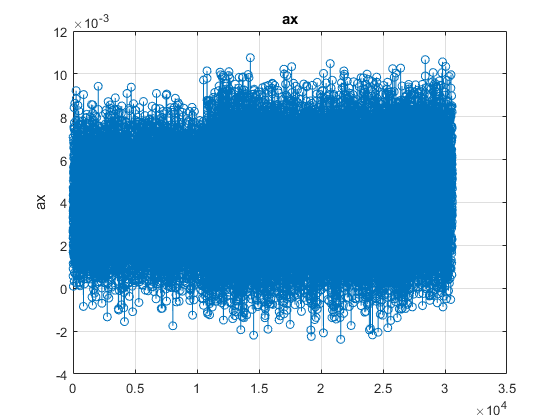

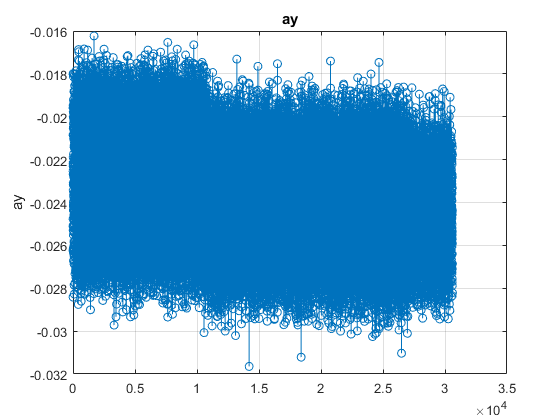

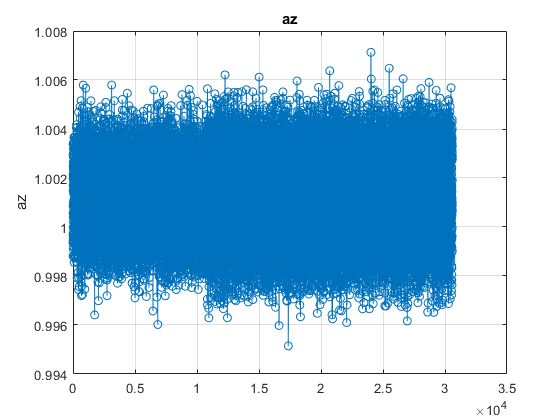

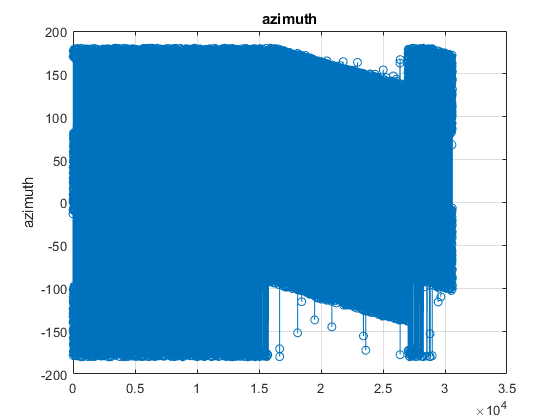

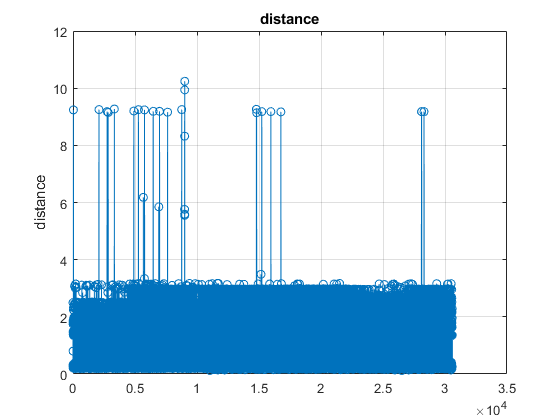

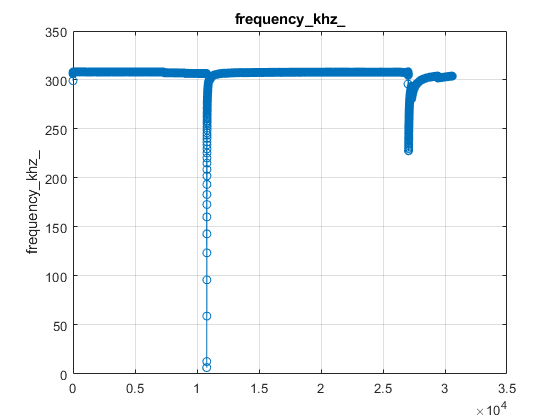

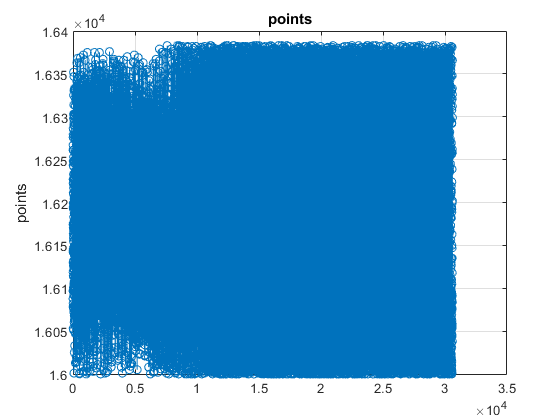

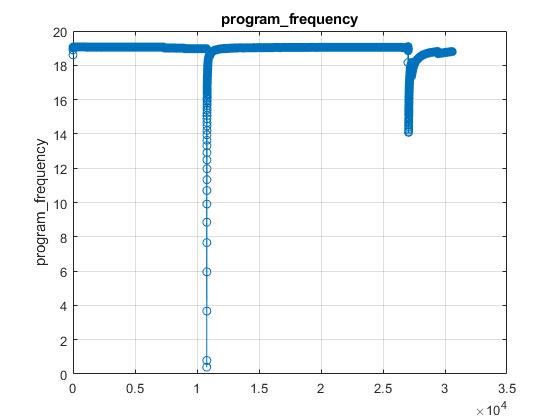


% 確認有資料
if isempty(T_all)
    error('沒有讀取到任何資料。');
end

% x 軸：time
x = T_all.time;

% 將 time 轉為 datetime 類型（如果需要的話）
x = datetime(x, 'InputFormat', 'HH:mm:ss.SS');

% 所有欄位
vars = T_all.Properties.VariableNames;

% 要畫的欄位（排除 time 與 program_time）
plot_vars = setdiff(vars, {'time', 'program_time'});

% 建立多張圖，每張圖畫一個變數對 time
% for idx = 1:numel(plot_vars)
%     figure(idx)
%     y = T_all.(plot_vars{idx});
%     plot(x, y, '-o');
%     title(plot_vars{idx}, 'Interpreter', 'none');
%     xlabel('time', 'Interpreter', 'none');
%     ylabel(plot_vars{idx}, 'Interpreter', 'none');
%     grid on;
% end

for idx = 1:numel(plot_vars)
    figure(idx)
    y = T_all.(plot_vars{idx});
    plot(y, '-o');
    title(plot_vars{idx}, 'Interpreter', 'none');
    ylabel(plot_vars{idx}, 'Interpreter', 'none');
    grid on;
end